%Universidad del Cauca - 2021-1
%Teoria de las telecomunicaciones 1
%Trabajo 2 - Grupo 12 - Nicolas Chicaiza y Nicolas Zambrano

clear; %Limpio Espacio de trabajo
clc;

A=1; %Amplitud rampa (Igual al taller 1)
sh=0.1; %Desplazamiento en el tiempo (Igual al taller 1)
T=4; %Periodo rampa (Igual al taller 1)
%framp=1/T %Frecuencia de rampa
np=0.001; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
fs=1/(T*np); %Frecuencia de muestreo
t=-(T+sh):np*T:(T+sh); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)


ramp=(A/T)*(t+sh); %Defino la pendiente de las rampas y creo el vector rampa con respecto al tiempo
ps=ramp.*rectpuls((t+sh)-(T/2),T); %Acoto el vector rampa con un pulso rectangular de origen en 0 y ancho Tr

%---------------------------CALCULO SIMBOLICO TRANSFORMADA--------------------------
%---------------------------Transformada pulso rampa--------------------------
syms x f;
dif=((A/T)*(x+sh)*exp(-i*2*pi*f*(x))); %Expresion dentro de la integral de la transformada de Fourier
trfu=int(dif,[0-sh T-sh]) %Integral definida en el periodo de la rampa

$$trfu = \frac{{\mathrm{e}}^{-\frac{39\,\pi \,f\,\mathrm{i}}{5}}\,\left(1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right)}{16\,f^{2}\,\pi^{2}}$$

trfu=simplify(abs(trfu))

$$trfu = \frac{{\mathrm{e}}^{\frac{39\,\pi \,\mathrm{imag}\left(f\right)}{5}}\,\left|1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right|}{16\,\pi^{2}\,{\left|f\right|}^{2}}$$

double(limit(trfu))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud del nivel DC

ans = 2

double(simplify(abs(subs(trfu,f,1))))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud en f=1

ans = 0.1592

%-----------------------------------------------------------------------------

%--------------------CALCULO FFT---------------------------
tic
Pt=1000;%Coeficiente multiplicador de cantidad de puntos en la transformada rapida de Fourier
N=Pt*(2^(nextpow2(length(ps))));%Calculo de la potencia de 2 mas cercana a la longitud de la señal de entrada (Para eficiencia computacional)
Xf=abs(fftshift(fft(ps,N)))/fs; % Transformada FFT Normalizada
f=linspace(-fs*0.5,fs*0.5,length(Xf));
%f=f./T;%Normalizacion en frecuencia
toc

Elapsed time is 0.134757 seconds.


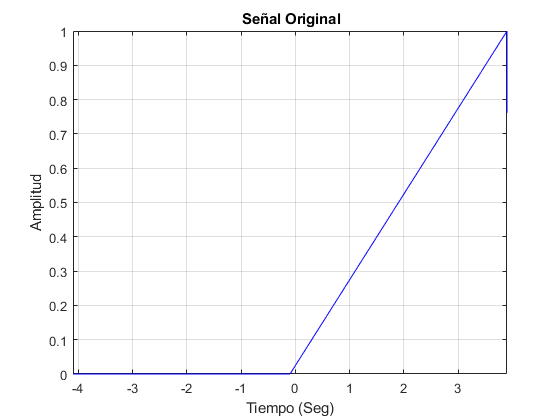

%-----------------------------------------------------------------------------

%--------------------Graficacion de Resultados---------------------------
plot(t,ps,'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-T-sh T-sh]); %Graficacion de Resultados
title('\bf Señal Original');

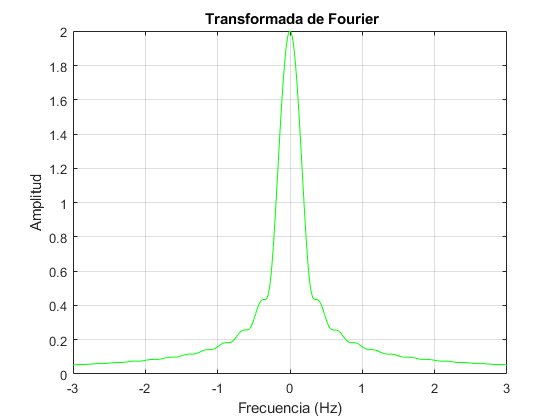

plot(f,Xf,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-3 3]); %Graficacion de Resultados
title('\bf Transformada de Fourier');

%-----------------------------------------------------------------------------